# COVID-19 Detection Usign X-Rays

by Joshua Rothe

## Image pre-processing, K-Means

K = 10;  % for K-means

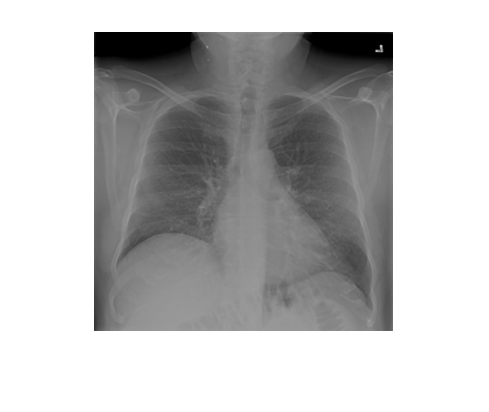

% Class - normal images
num_images = 2000; % Number of images in train dataset is 1-8000
normal_img = zeros((299*299),num_images);   % Initialize empty array
for i = 1:num_images
    filename = sprintf('./data/normal/Normal-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    % img = imsegkmeans(img,K);
    normal_img(:,i) = double(reshape(img,[],1));    % reshapes image as column vector
end                                                 % and adds it to normal_img
labels(1:num_images,1) = "normal";
imshow(img);

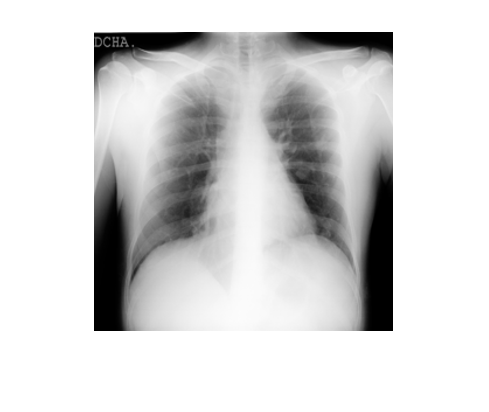

% Class - COVID
num_images2 = 1000; % Number of images in training dataset is 1-3000
cov_img = zeros((299*299),num_images2);  % Initialize empty array
for i = 1:num_images2
    filename = sprintf('./data/COVID/COVID-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    % img = imsegkmeans(img,K);
    cov_img(:,i) = double(reshape(img,[],1));       % reshapes image as column vector
end                                                 % and adds it to cov_img
labels(num_images+1:num_images2+num_images,1) = "COVID";
imshow(img);

% Combine images and labels
train_images = [normal_img, cov_img];
train_labels = labels;

## Apply PCA

%% Train and find the PCA dimensions of the training data
% First reduce the training data to a computationally manageable size
% (note: in this instance, size is unchanged, but may adjust as needed)
train_size = num_images + num_images2;
base = 50;         % Base size, given
% Reduced variables are for if we reduce the number if pics taken from
% dataset.
train_images_reduced = train_images(:,[1:train_size]);
train_labels_reduced = train_labels([1:train_size],:);
% Normalize the data, will be calling it X for simplicity
X = train_images_reduced;
Xmean = mean(X);    % mean of X
Xnorm = X - Xmean;  % normalized
% Calculate covariance matrix
covar_matrix = (Xnorm' * Xnorm) / (train_size - 1);
% Calculate Eigenvectors and Eigenvalues of Covariance Matrix
[Xeivec, Xeival] = eig(covar_matrix);
% Now project the dataset
proj_train = Xnorm * Xeivec;
% Back into larger data format
Xnormk_train = proj_train * Xeivec';

## Create Models

% Create a model with standard params
Mdl = fitcecoc(Xnormk_train',train_labels_reduced');
% Note: This model performs poorly. More than 50% error when 
% tested using predict().
% error = resubLoss(Mdl)  % resubloss error

% Obtain better model performance with parameters
t = templateSVM('Standardize',true);
Mdl2 = fitcecoc(Xnormk_train',train_labels_reduced',...
    'Learners',t,'ClassNames',{'normal','COVID'});

% options = statset('UseParallel',true);
% CVMdl2 = crossval(Mdl2,'Options',options);
% kFoldError2 = kfoldLoss(CVMdl2) % kfoldloss error from cross validated model

% Create model with optimized parameters
t = templateSVM('Standardize',true,'KernelScale', 107.7, ...
    'BoxConstraint', .0010908);
Mdl3 = fitcecoc(Xnormk_train',train_labels_reduced',...
    'Learners',t,'Coding',"onevsall",'ClassNames',{'normal','COVID'});

% options = statset('UseParallel',true);
% CVMdl3 = crossval(Mdl3,'Options',options);
% kFoldError3 = kfoldLoss(CVMdl3) % kfoldloss error from cross validated model

## Test Models

% Return a vector of predicted values, should all be non-COVID.
% test data is 8001 - 8100
clear test_label_healthy2; clear test_data_healthy; 
clear test_label_healthy3; k = 1;
%test_data_healthy = zeros((299*299),(8100-8001+1));   % Initialize empty array
for i = 7001:8000
    filename = sprintf('./data/normal/Normal-%i.png', i);
    img = (imread(filename));
    test_data_healthy(:,k) = double(reshape(img,[],1));    % reshapes image as column vector
    k = k + 1;  % increment k for matrix pos
end
[test_label_healthy2] = predict(Mdl2,test_data_healthy');
[test_label_healthy3] = predict(Mdl3,test_data_healthy');

% Return a vector of predicted values, should all be all COVID infections.
% test data is 2001 - 3000
clear test_label_covid2; clear test_data_covid; 
clear test_label_covid3; k = 1;
%test_data_covid = zeros((299*299),(3101-3001+1));   % Initialize empty array
for i = 2001:3000
    filename = sprintf('./data/COVID/COVID-%i.png', i);
    img = (imread(filename));
    test_data_covid(:,k) = double(reshape(img,[],1));    % reshapes image as column vector
    k = k + 1;  % increment k for matrix pos
end
[test_label_covid2] = predict(Mdl2,test_data_covid');
[test_label_covid3] = predict(Mdl3,test_data_covid');

### Mdl2 - Default Paramaters

Accuracy with both the Healthy and COVID datasets was observed to try and see if the model skewed towards false positives or false negatives.

#### Healthy Test

% Check performance by counting number of times correct value was reached
perf_healthy_temp2a = categorical(test_label_healthy2);
labels_perf2a = categories(perf_healthy_temp2a) % displays labels

labels_perf2a = 2×1 cell array
    {'COVID' }
    {'normal'}


perf_healthy2a = countcats(perf_healthy_temp2a) % displays occurance per label

perf_healthy2a =     70
   930


Mdl2 with no K-Means is 93.0% accurate at detecting healthy images.

With K = 3 it is 72.8% accurate.

With K = 5 it is 69.8% accurate.

With K = 10 it is 92.4% accurate.

#### COVID Test

% Check performance by counting number of times correct value was reached
perf_covid_temp2b = categorical(test_label_covid2);
labels_perf2b = categories(perf_covid_temp2b) % displays labels

labels_perf2b = 2×1 cell array
    {'COVID' }
    {'normal'}


perf_covid2b = countcats(perf_covid_temp2b) % displays occurance per label

perf_covid2b =    291
   709


Mdl2 with no K-Means is 70.9% accurate at detecting COVID infection.

With K = 3 it is 89.2% accurate.

With K = 5 it is 70.4% accurate.

With K = 10 it is 89.7% accurate.

### Mdl3 - Optimized Paramaters

Same as Mdl2 except with the optimized model. Results are greatly improved.

#### Healthy Test

% Check performance by counting number of times correct value was reached
perf_healthy_temp3a = categorical(test_label_healthy3);
labels_perf3a = categories(perf_healthy_temp3a) % displays labels

labels_perf3a = 2×1 cell array
    {'COVID' }
    {'normal'}


perf_healthy3a = countcats(perf_healthy_temp3a) % displays occurance per label

perf_healthy3a =      2
   998


Mdl2 with no K-Means is 99.8% accurate at detecting healthy images.

With K = 3 it is 88.4% accurate.

With K = 5 it is 100.0% accurate.

With K = 10 it is 99.7% accurate.

#### COVID Test

% Check performance by counting number of times correct value was reached
perf_covid_temp3b = categorical(test_label_covid3);
labels_perf3b = categories(perf_covid_temp3b) % displays labels

labels_perf3b = 1×1 cell array
    {'normal'}


perf_covid3b = countcats(perf_covid_temp3b) % displays occurance per label

perf_covid3b = 1000

Mdl3 with no K-Means is 100.0% accurate at detecting COVID infection.

With K = 3 it is 93.0% accurate.

With K = 5 it is 99.7% accurate.

With K = 10 it is 99.5% accurate.